# Goodput Calculation in LR-FHSS Networks

#### Based on "Asynchronous Contention Resolution-Aided ALOHA" (João Luiz Rebelatto)

## Variables

header_duration=0.233472; % Header duration
payload_duration=0.102400; % Fragment duration
b = 10; % Payload length (in bytes)
CR = 1/3; % Coding rate
Headers = 3; % Headers replicates
C = 35; % Number of physical channels
l = 0.900; % Average interarrival
Devices_theo=[1000, 5000, 10000, 15000, 20000, 25000, 30000, 35000, 40000, 45000, 50000, 55000, ...
60000, 65000, 70000, 75000, 80000, 85000, 90000, 95000, 100000, 105000, 110000, 115000, 120000, ...
125000, 130000, 135000, 140000, 145000, 150000]; %Number of devices
f = ceil((b+3)/(6*CR)) % Number of payload fragments

f = 7

gamma = ceil(f*CR) % Minimum required number of fragments

gamma = 3

lambda_h = 900; % Interarrivel between Headers
lambda_f = 900; % Interarrivel between Payload fragments
lambda = 900; %Mudança Prof Jamil
transceiver_wait = 0.006472; %Mudança Prof Jamil


## Equations

for i=1:length(Devices_theo) %Mudança Prof Jamil
    number_nodes=Devices_theo(i)/8;
    
    threshold=ceil(f*CR); %Mudança Prof Jamil

    u_h = (number_nodes*Headers)/lambda; %Mudança Prof Jamil
    u_f = (number_nodes*f)/lambda; %Mudança Prof Jamil

    %A_h = 2*lambda_h*th + lambda_f*(th + tf); % Vulnerable interval of the given copy of Header
    %A_f = 2*lambda_f*tf + lambda_h*(th + tf); % Vulnerable interval of the given copy of Payload Fragment
    A_h=max(1, u_h*2*header_duration+u_f*(header_duration+payload_duration+transceiver_wait));
    A_f = max(1, u_f*2*payload_duration + u_h*(header_duration+payload_duration+transceiver_wait));


    P_h = 1 - (1-(1 - 1/C).^(A_h-1)).^Headers; %Probability of receiving at least 
    % one header

    %Daqui para frente, perguntar como calcular a probabilidade Gamma
    P1 = (1 - 1/C).^(A_f - 1); % Probability of successfully receiving one payload fragment

    %% binopdf(k, n, p) computes the binomial probability for k successes in n trials with success probability p
    range = 1:1:threshold;
    aux=0;
    

    %P_gamma = 1 - sum(binopdf(0:(gamma-1), f, P1)); % Probability of successfully receiving at least 'gamma' fragments
    for k=1:length(range) % PERGUNTAR

        loop=k-1;
        aux=aux+nchoosek(f, loop)*(P1.^loop).*(1-P1).^(f-loop);
    end
    P_F = 1 - aux;
    PacketSuccessProbability=(P_F.*P_h);
    Goodput(i)=(PacketSuccessProbability*b*number_nodes*(1/lambda));


end

## Graph plot

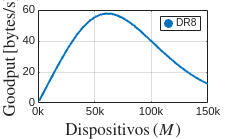

ax =   Axes with properties:

             XLim: [0 150]
             YLim: [0 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1249 0.7750 0.8001]
            Units: 'normalized'

  Show all properties


%% Figure 1
figure (1);
h=plot(Devices_theo/1000, Goodput, '-', 'Color', [0.000, 0.447, 0.741], 'MarkerFaceColor', [0.000, 0.447, 0.741], 'LineWidth', 1.5, 'MarkerSize',8);
hold on;
grid on;

clear plot_legend;

plot_legend(1) = plot(inf, inf, 'o', 'Color', [0.000, 0.447, 0.741], 'MarkerFaceColor', [0.000, 0.447, 0.741], 'MarkerSize',8);

l = legend(plot_legend, 'DR8');

grid on;
ylabel('$\mathrm{Goodput}\,\mathrm{[bytes/s]}$','Interpreter','LaTeX','Fontsize',13);
xlabel('$\mathrm{Dispositivos}\,{(M)}$','Interpreter','LaTeX','Fontsize',13);

ax = ancestor(h(1), 'axes');  % usa apenas o primeiro handle
ax.XAxis.Exponent = 0;
%ax = ancestor(h, 'axes')
%ax.XAxis.Exponent = 0
ax.XAxis.TickLabelFormat = '%.0fk'